# Brake-Reuß Beam - DIC data

We consider digital image correlation measurements from a shaker ringdown test on a beam with a bolted lap joint [1]. Oscillations are assumed lie close to its slowest 2D spectral submanifold (SSM), which will be identified and used for model reduction.

The dataset contains beam full-field (206 points in 720 mm of beam length) of the displacements of the bottom side measured via DIC and accelerations measured via accelerometers (ACC) in 2 locations. All data refers to a single experimental trial, acquired with different measurement devices. The dataset also includes backbone curves results obtained using the PFF method based on accelerometer signals. 

Here we construct a reduced-order model using DIC data and we validate it on the acceleration signals.

clearvars
close all

[1] Kosova G. et al. (2021) Nonlinear System Identification of a Jointed Structure Using Full-Field Data: Part II Analysis. In: Kerschen G., Brake M.R., Renson L. (eds) Nonlinear Structures & Systems, Volume 1. Conference Proceedings of the Society for Experimental Mechanics Series. Springer, Cham. https://doi.org/10.1007/978-3-030-47626-7_27

## Experimental Data

We will divide the data into a training set, for model fitting, and a test set, for validation. In this case the experimental data consists of two measurements, and we will use both trajectories as the training set and the first one as the test set. We plot the measurements for inspection.

load data_BRB.mat

data_BRB

data_BRB = struct with fields:
            TimeDIC: [15260×1 double]
    DisplacementDIC: [206×15260 double]
            TimeACC: [1×272128 double]
    AccelerationACC: [2×272128 double]
              Xmesh: [1×206 double]
              Units: [1×1 struct]
        LocationACC: [2×1 double]
      PFFResultsACC: [1×1 struct]


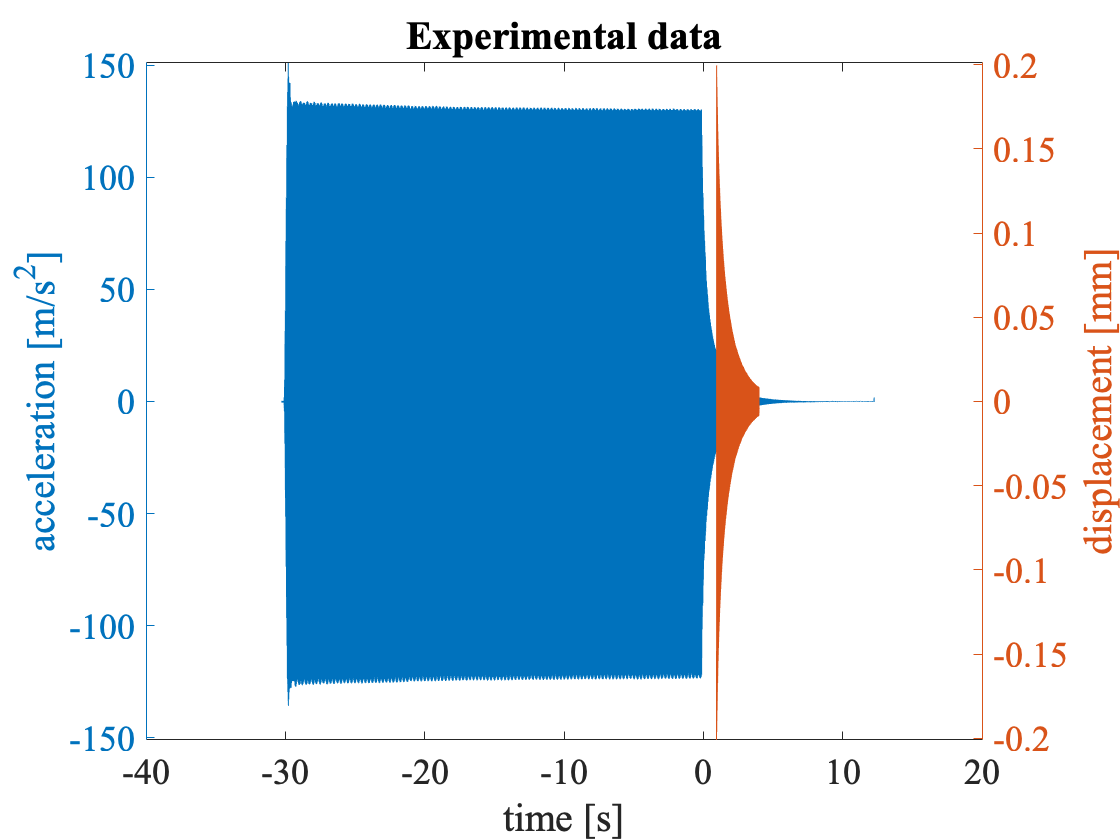


Xmesh = data_BRB.Xmesh;
uData = cell(1,2);
uData{1,1} = data_BRB.TimeDIC;
uData{1,2} = data_BRB.DisplacementDIC;

aData{1,1} = data_BRB.TimeACC;
aData{1,2} = data_BRB.AccelerationACC;

figure;
set(gca,'fontname', 'times'); set(gca,'fontsize', 18); title('Experimental data')
yyaxis left
plot(aData{1,1}, aData{1,2}(2,:))
ylabel('acceleration [m/s^2]'); ylim([-1 1]*max(abs(aData{1,2}(2,:))))
yyaxis right
plot(uData{1,1}, uData{1,2}(183,:)); ; ylim([-1 1]*max(abs(uData{1,2}(183,:))))
xlabel('time [s]'); ylabel('displacement [mm]');
set(gca,'fontname', 'times'); set(gca,'fontsize', 18); title('Experimental data')

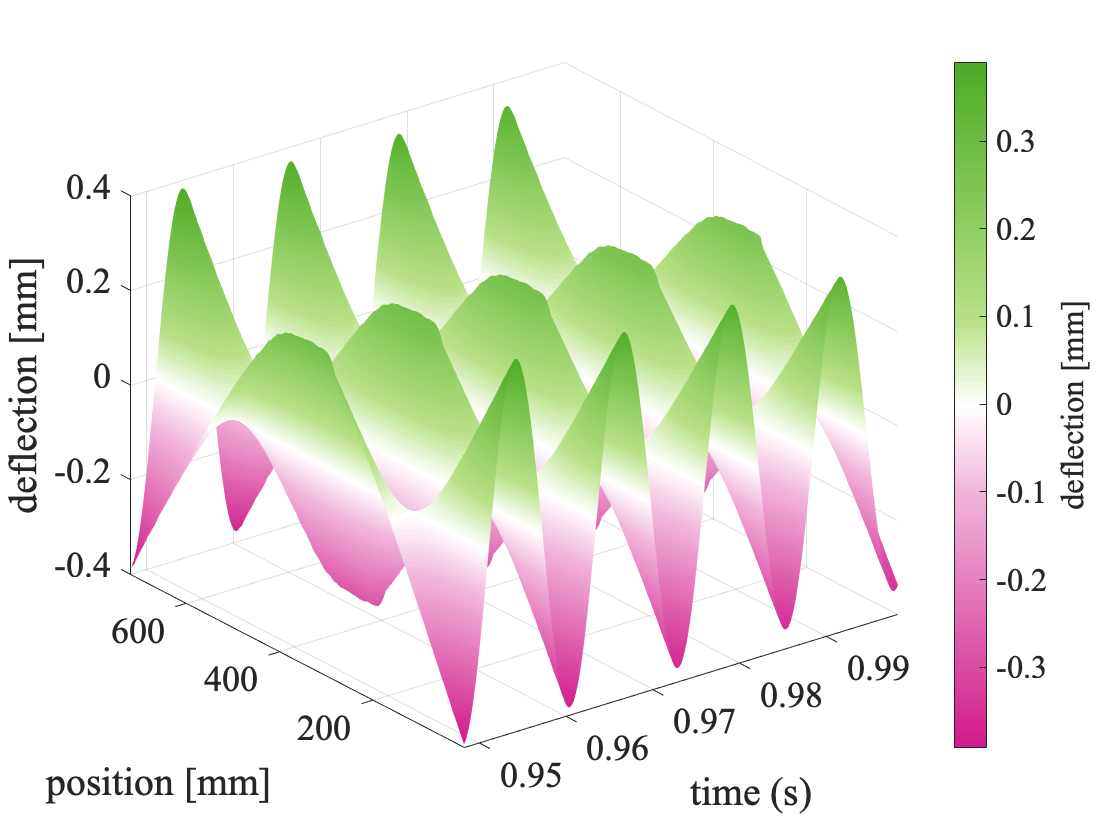

figure
map = pinkgreen(101);
[TT,XX] = meshgrid(uData{1,1},Xmesh);
surf(TT,XX,uData{1,2})
set(gca,'FontName','Times')
set(gca,'FontSize',18)
xlabel('time (s)')
ylabel('position [mm]')
zlabel('deflection [mm]')
shading  interp
colormap(map)
h = colorbar;
ylabel(h, 'deflection [mm]')
xlim([0 1/80*4]+uData{1,1}(1))
ylim([Xmesh(1) Xmesh(end)])

## Delay embedding

Now we arrange the scalar measurements in an observable space of dimension at least $2m+1$, with $m$ the dimension of the manifold. This guarantees that the manifold from the full state space can be embedded in the observable space. The dimensionality of the observable space can be further expanded with the parameter `overEmbed` to facilitate recognition of the manifold from data.

We form a multi-dimensional observable by stacking $d$ subsequent scalar measurements $x$ in a vector $y$, and we will later use the trajectories in this augmented space for the manifold fitting.


$$\left[
\begin{array}{c}
y_{1} \\ \vdots \\ y_{i+1} \\ \vdots \\ y_{d+1}
\end{array} 
\right] = 
\left[
\begin{array}{c}
x(t^k) \\ \vdots \\ x(t^k+i\Delta t) \\ \vdots \\ x(t^k+d\Delta t)
\end{array} 
\right]$$


overEmbed = 5;
shiftSteps = 1;
SSMDim = 2;

yData = coordinates_embedding(uData, SSMDim, 'OverEmbedding', overEmbed, 'ShiftSteps', shiftSteps);

The 1236 embedding coordinates consist of the 206 measured states and their 5 time-delayed measurements.


## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace $V_e$. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

 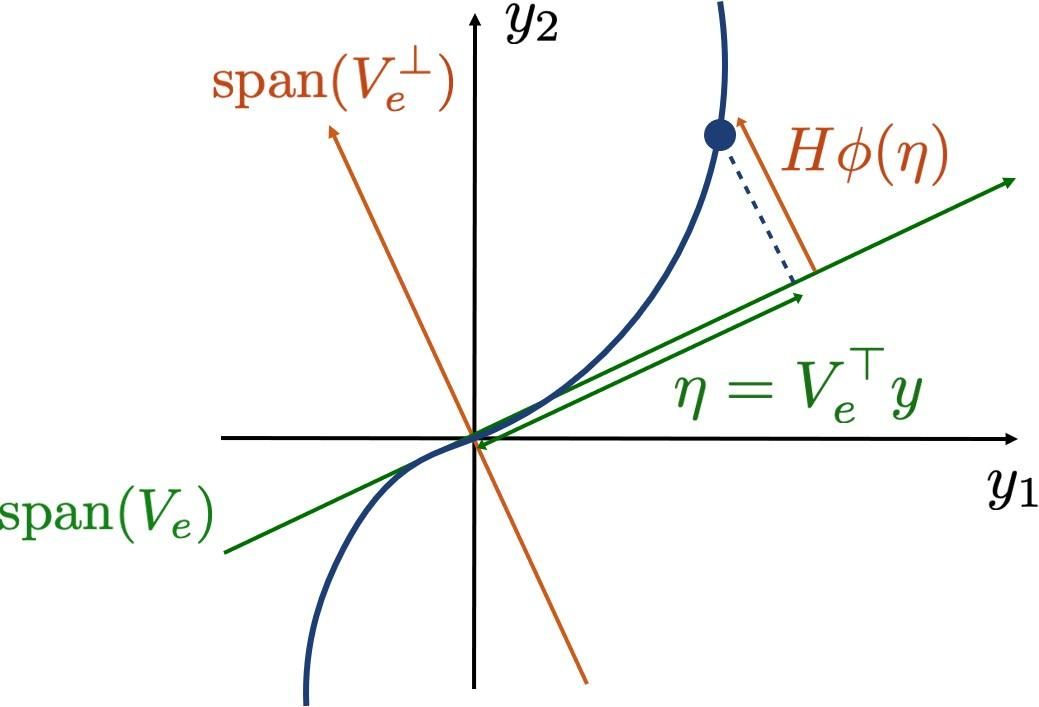

We seek the $2N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y) $,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem amounts to minimizing a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top y_k - H\phi_{m,2:M}(V_e^\top y_k) ||$$


to find $H$ and the $2N\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab function `fmincon` in `IMparametrization`.

SSMOrder = 1;
[V, SSMFunction, mfdInfo] = IMparametrization(yData, SSMDim, SSMOrder);

## Plot and validation

Now that we have computed the eigenspace of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto the eigenspace. 

etaData = getProjectedTrajs(yData, V);

We plot the test and training set trajectories projected onto the plane $$V$$.

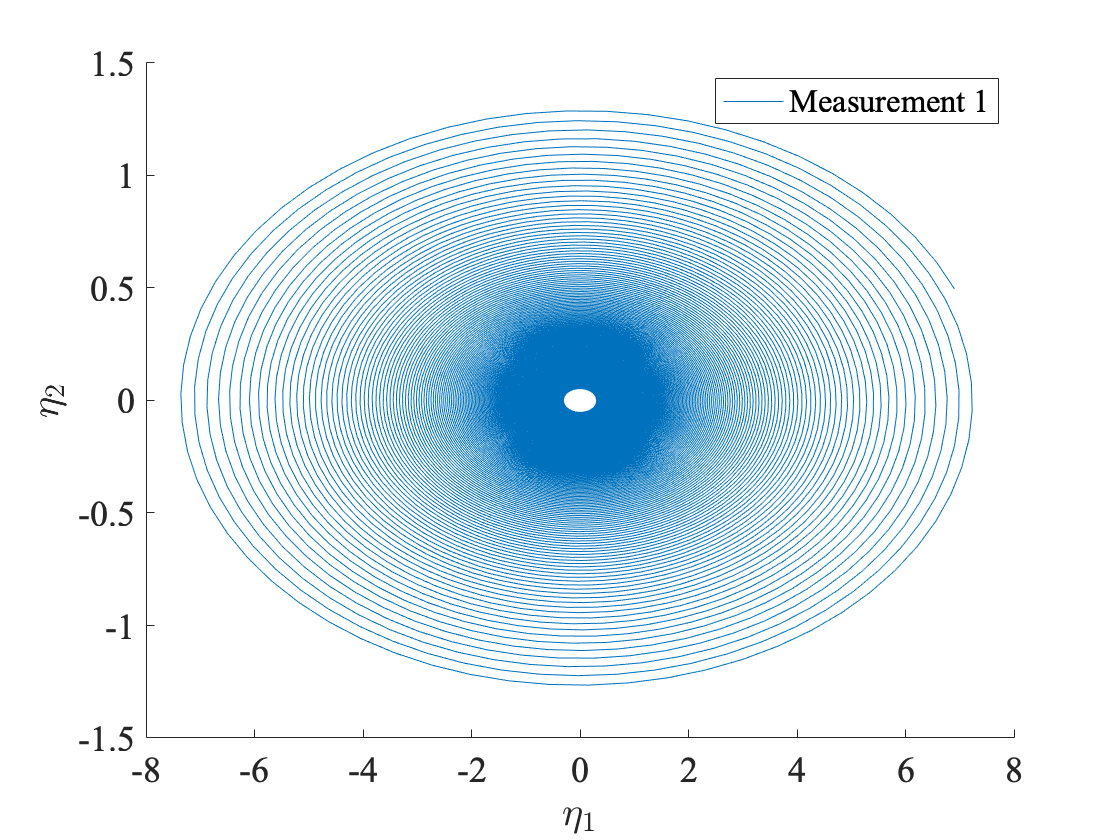

plotReducedCoords(etaData);

Furthermore, we draw the first component of the manifold shape along with the trajectory from the training set. 

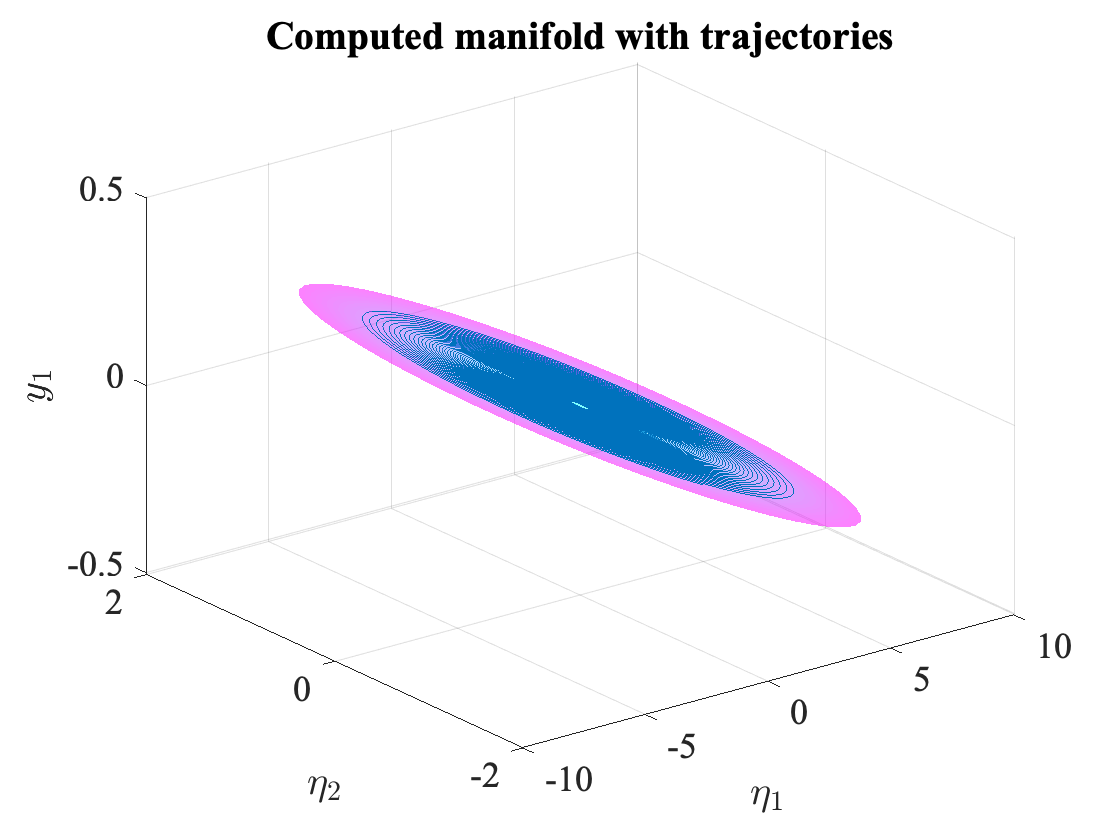

plotSSMWithTrajectories(yData, SSMFunction, 1, V, 30, 'SSMDimension', SSMDim)

## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMdynamics_flow` fits a polynomial map


$$\dot{\eta} = W_r \phi(\eta)$$


where $\phi(\eta)$ again computes a vector of all monomials of $\eta$, and $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics on a normal form, and seek the Taylor expansion of a map $N$ fulfilling


$$\dot{z} = N(z) \approx Dz + W_n\phi(z)$$


with $D$ a diagonal matrix and $W_n$ containing coefficients for the near-resonant nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(\eta) \approx \eta + W_t \phi(\eta)$$


with $W_t$ containing the coefficients for the nonlinear terms of the coordinate change.

The optimization is performed in `IMDynamics_flow` with the Matlab function `fminunc`. We apply a regularization on the polynomial coefficients to prevent overfitting. The regularization parameter is optimized from a logarithmic range of values with ridge regression. 

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1         0.286675                          16.3
     1           4        0.0959678      0.0012264           12.7  
     2           6        0.0829365       0.147808          0.976  
     3           7        0.0825254              1          0.979  
     4           8        0.0820653              1          0.492  
     5           9        0.0816458              1          0.489  
     6          10        0.0801781              1            1.3  
     7          12        0.0791725       0.354839           2.56  
     8          13        0.0745125              1           3.64  
     9          14        0.0670506              1           3.84  
    10          15        0.0445048              1           3.14  
    11          16

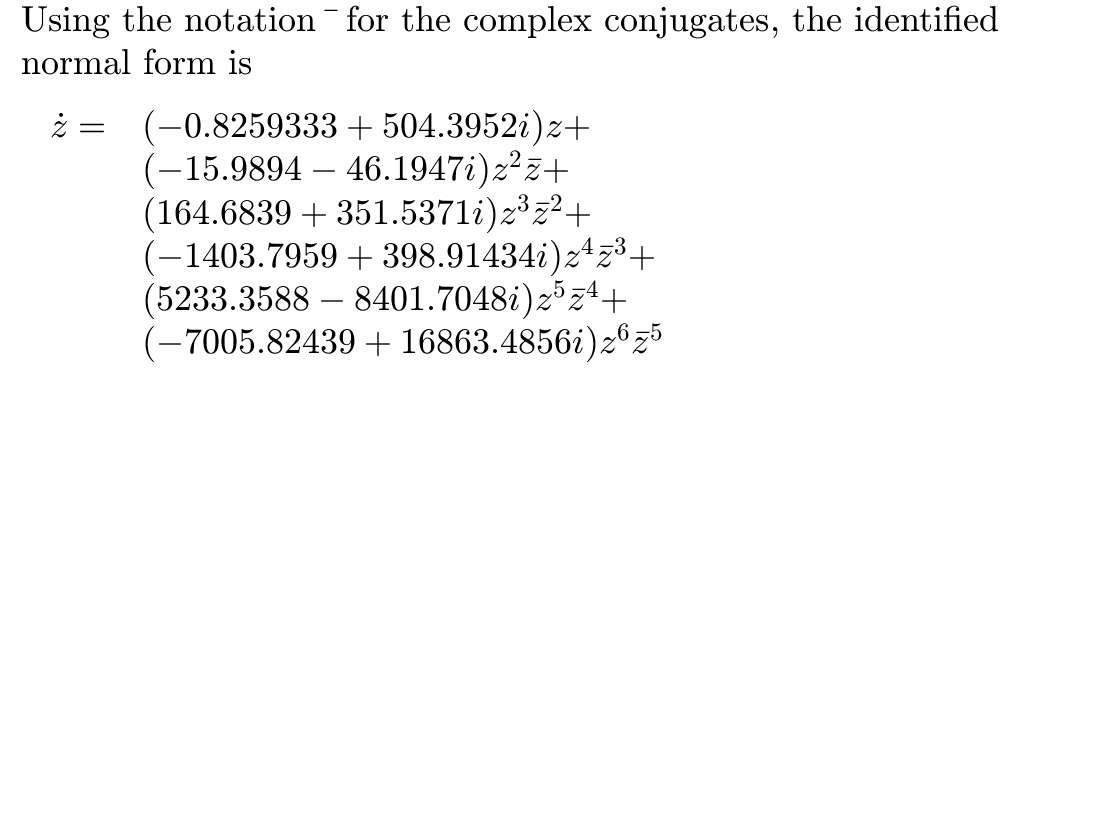

ROMOrder = 11;
Nfolds = 5;
Nregvals = 30; 
[~,Tinv,N,T,NormalFormInfo] = IMdynamics_flow(etaData, 'R_PolyOrd', ROMOrder, 'n_folds', Nfolds, 'l_vals', logspace(-6,0,Nregvals), 'style', 'normalform');

We transform the truncated initial condition of our test trajectory according to the obtained change of coordinates, and integrate our reduced order evolution rule to predict the development of the trajectory. 

zData = transformComplex(Tinv, etaData);
[zRec, yRec] = integrateFlows(N, zData, @(q) SSMFunction(T(q)));
etaRec = transformComplex(T, zRec);

## Evaluation of reduced dynamics

The error RRMSE is computed as the average distance of the predicted trajectories to the measured ones in the observable space.

[reducedTrajDist, fullTrajDist] = computeRecDynErrors(etaRec, yRec, etaData, yData);
RRMSE = mean(fullTrajDist)

RRMSE =      0.093612


We plot the measured test set trajectory in the reduced coordinates and compare it to the prediction. 

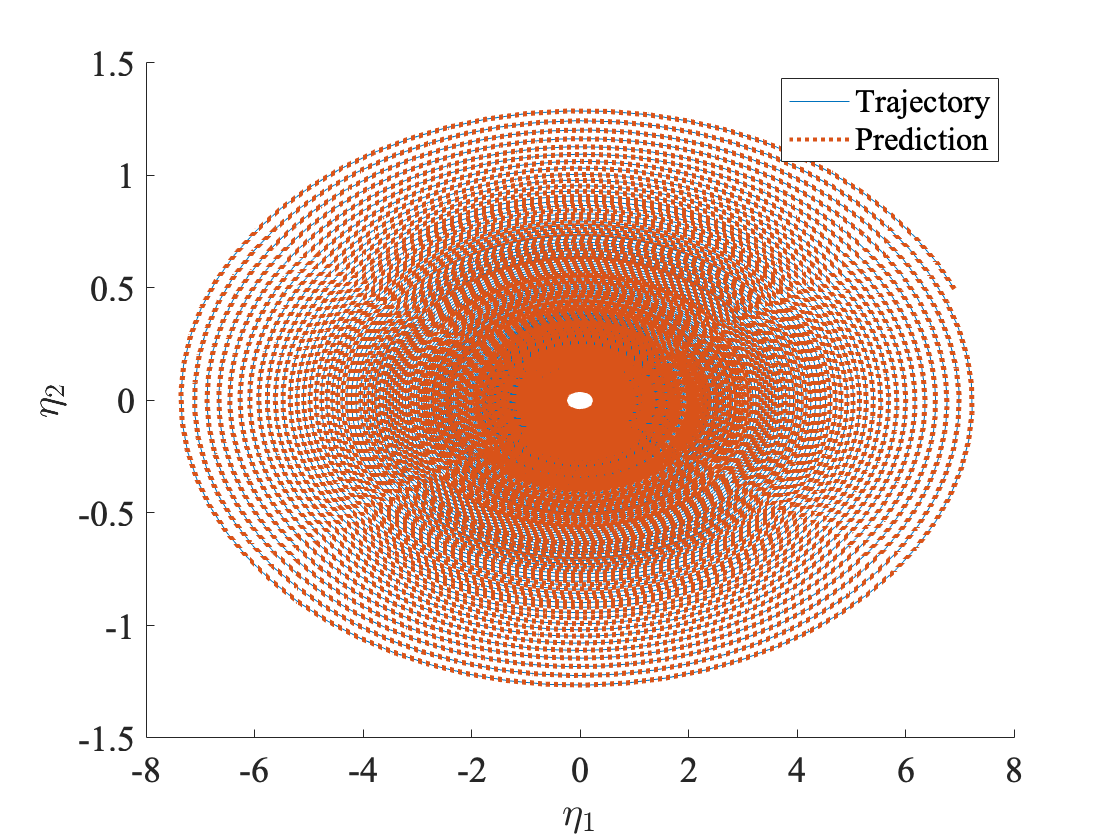

plotReducedCoords(etaData, etaRec)
legend({'Trajectory', 'Prediction'})

We also plot the measured and predicted tip acceleration.

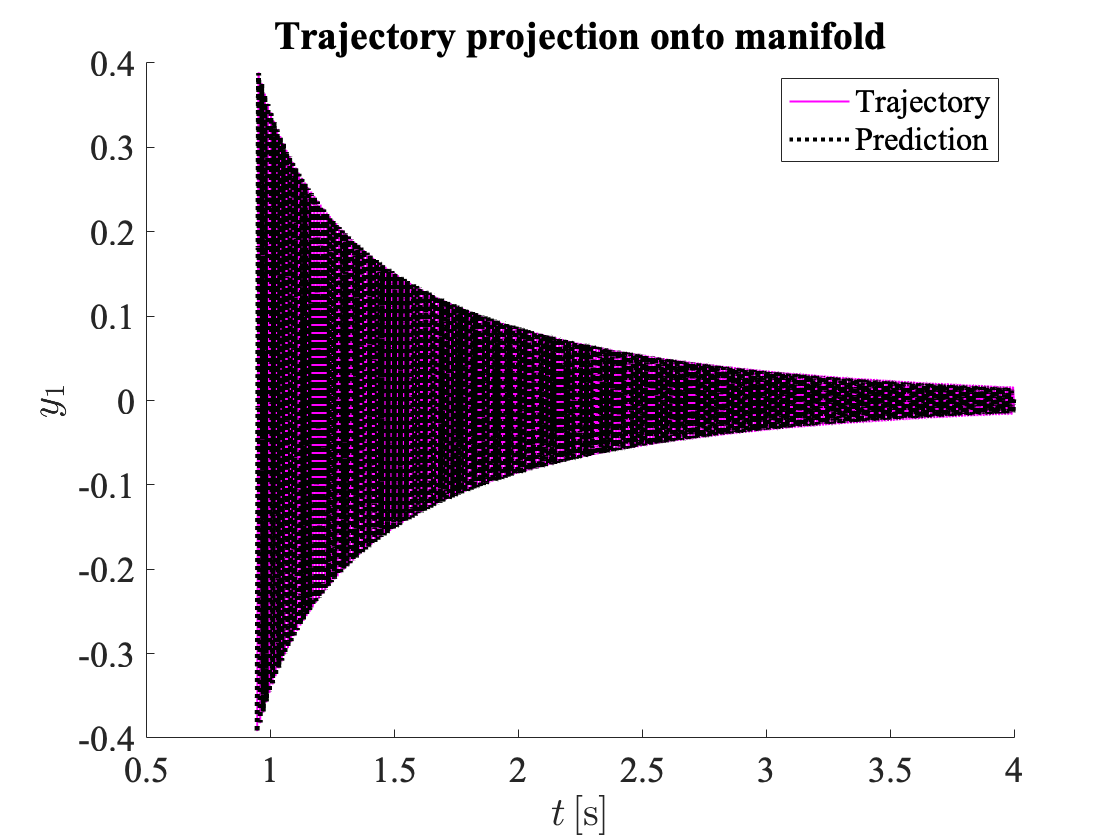

plotReconstructedTrajectory(uData, yRec, 1, 'm')
legend({'Trajectory', 'Prediction'})
xlabel('$t \, [$s$]$','interpreter','latex'); 

Finally we estimate the eigenvalues of the linearized system.

normalFormEigenvalues = computeEigenvaluesFlow(NormalFormInfo)

normalFormEigenvalues =      -0.82593 +      504.4i
     -0.82593 -      504.4i


## Backbone curves

With the knowledge of the coefficients of the normal form, we extract backbone curves for the instantaneous damping and frequency. The instantaneous damping is strongly nonlinear, but the frequency remains virtually unchanged in our model.

Plotting figure with the polar normal form equations ... Done. 


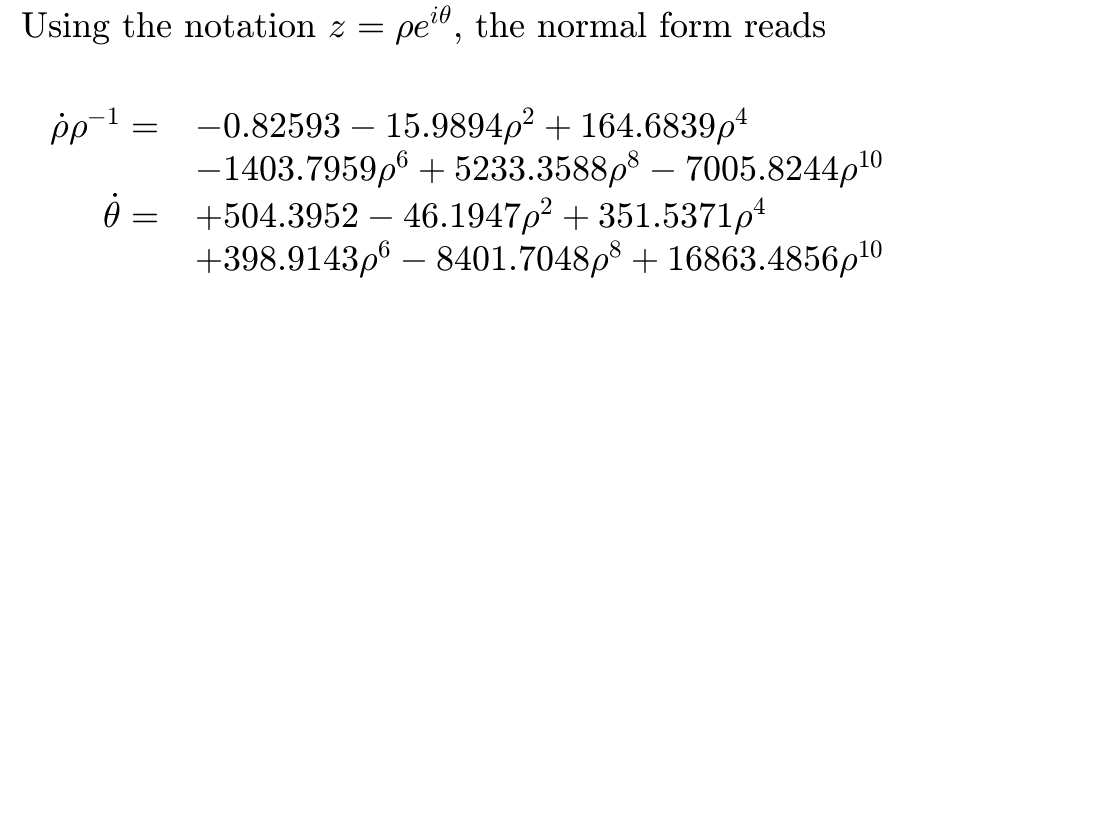

N_info = NormalFormInfo.N;
[damp, freq] = polarnormalform(N_info.coeff, N_info.exponents, N_info.phi);

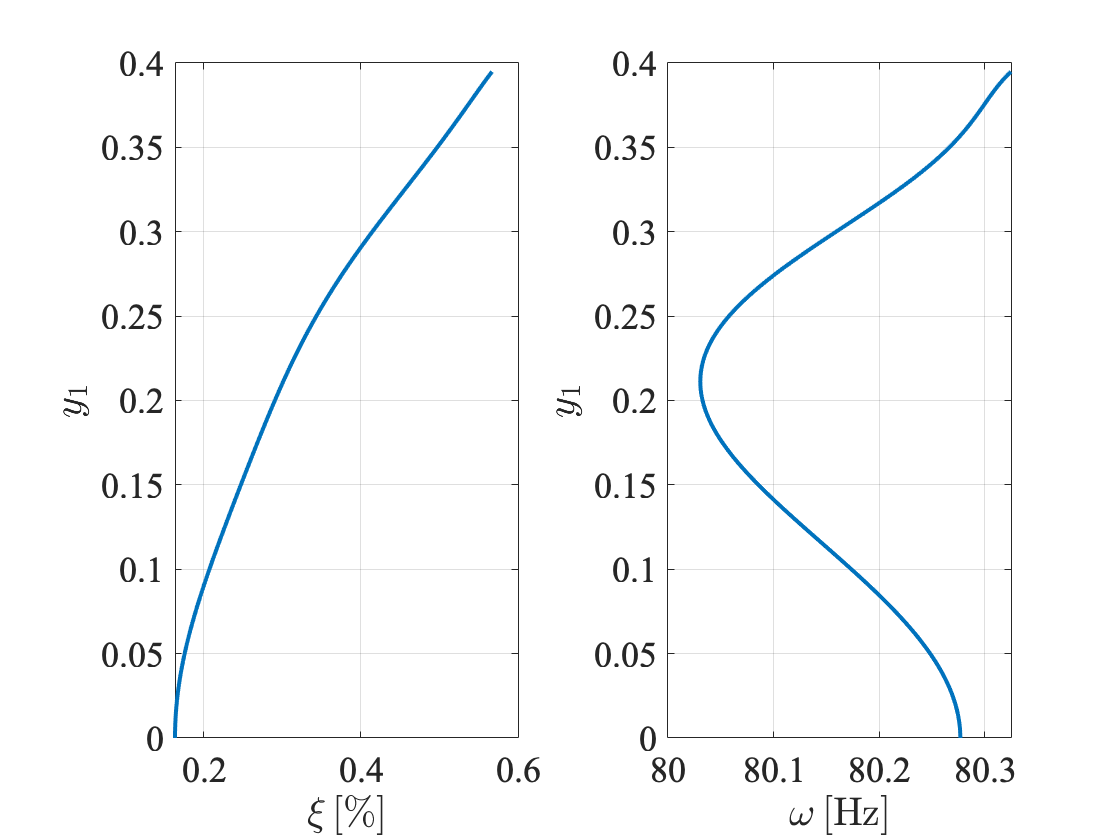


maxRho = abs(zData{1,2}(1,1));
figure
backbonecurves(damp, freq, SSMFunction, T, 1, maxRho, 'Hz');

## Validation with Accelerations

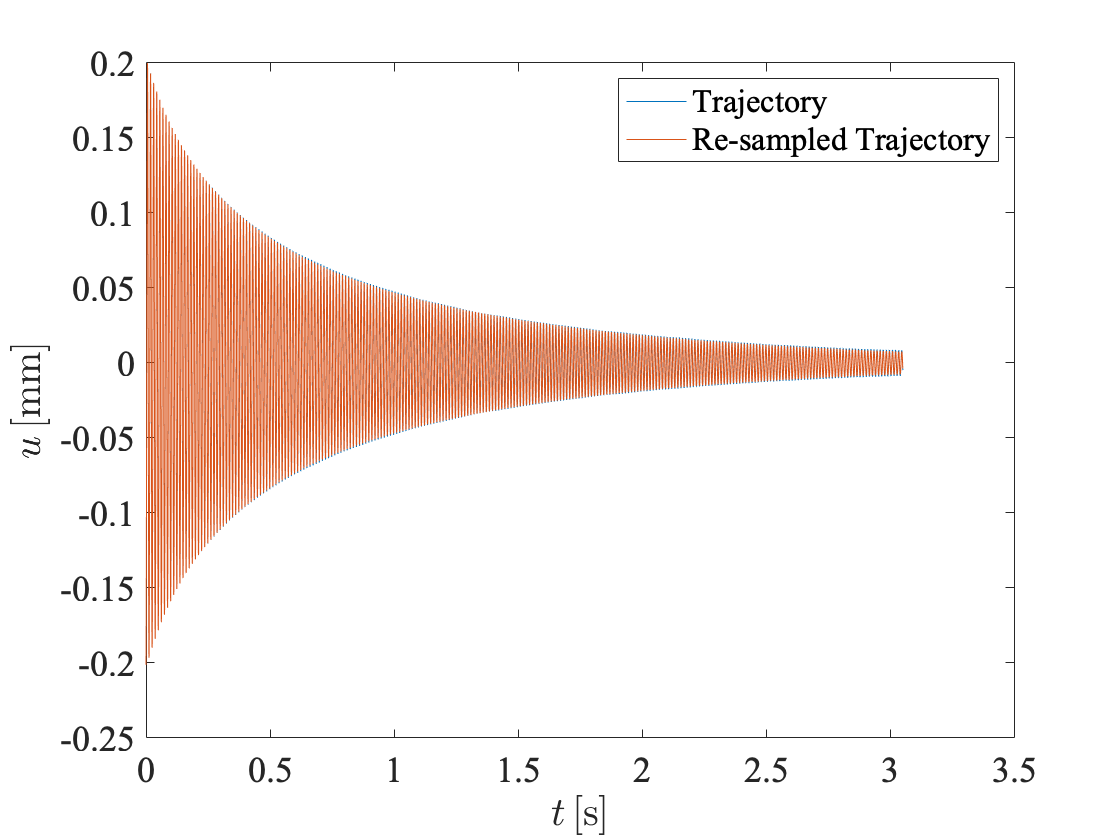

% Select Accelerometer Location
idx_acc = 1;
aData{1,1} = data_BRB.TimeACC;
aData{1,2} = data_BRB.AccelerationACC;

% Need to simulate with different sampling time
dtAcc = aData{1,1}(2)-aData{1,1}(1);
dtDIC = uData{1,1}(2)-uData{1,1}(1);
if dtAcc~=dtDIC
    uDataRef=cell(1,2);
    tDis = uData{1,1}(1):dtAcc:uData{1,1}(end); tDis = tDis-tDis(1);
    
    [tDis,zRecRef] = ode45(@(t,x) N(x),tDis,zData{1,2}(:,1));
    yRecRef = SSMFunction(T(transpose(zRecRef)));
    uDataRef{1,1} = transpose(tDis); uDataRef{1,2} = yRecRef(1:206,:);
end
rhoDis = transpose(abs(zRecRef(:,1)));
figure
plot(uData{1,1}-uData{1,1}(1),uData{1,2}(183,:),uDataRef{1,1},uDataRef{1,2}(183,:))
xlabel('$t \, [$s$]$','interpreter','latex'); 
ylabel('$u \, [$mm$]$','interpreter','latex'); 
legend('Trajectory','Re-sampled Trajectory')
set(gca,'fontname', 'times'); set(gca,'fontsize', 18); 

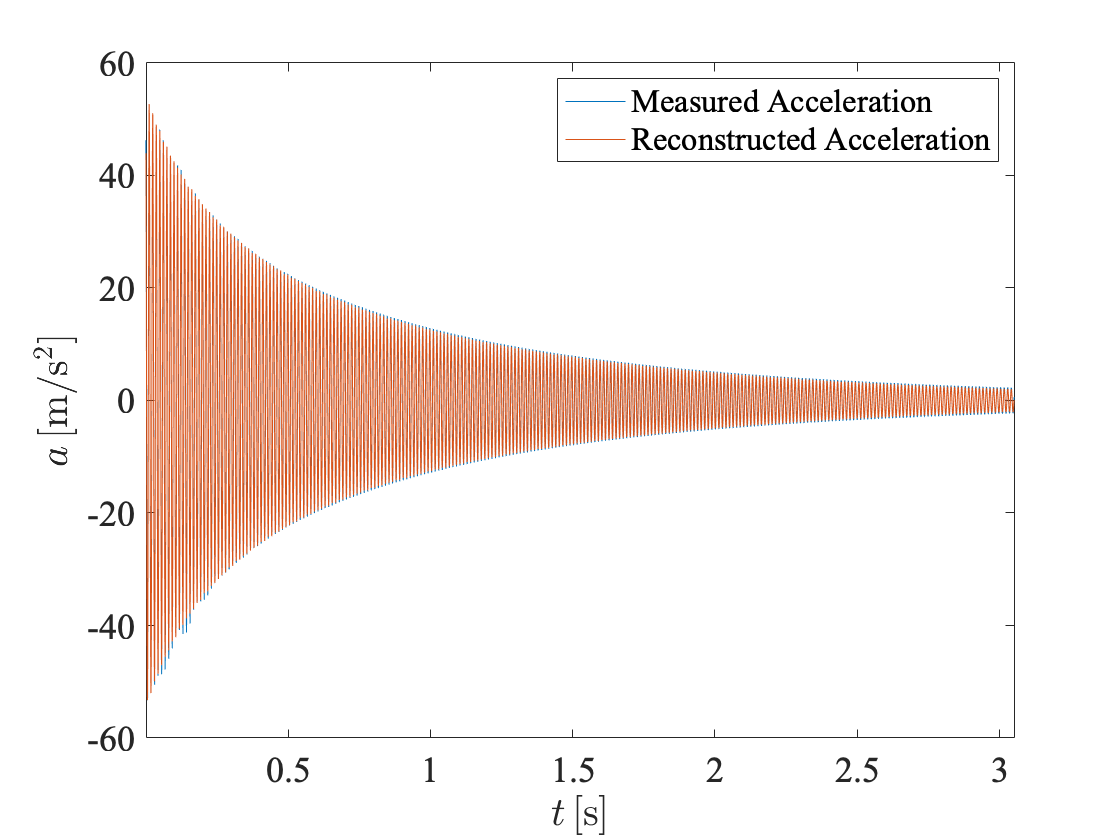


% Numerical Differentiation on the reconstructed data
tRec = uDataRef{1,1};
URec = uDataRef{1,2}/1e3; n_steps = 3;
[VRec,URec,tRec] = finitetimedifference(URec,tRec,3);
[ARec,VRec,tRec] = finitetimedifference(VRec,tRec,3);
rhoRec = rhoDis(2*n_steps+1:end-2*n_steps);
dampDIC = damp(rhoRec); freqDIC = freq(rhoRec);
damprDIC = -dampDIC./freqDIC; freqDIC = freqDIC/2/pi;

% Linear Interpolation among nodes
tAcc = aData{1,1}; aAcc = aData{1,2}(idx_acc,:); 
loc_acc = data_BRB.LocationACC(idx_acc);
idxs_acc_DIC =sum(Xmesh<loc_acc)+[0 1];

aRec = (ARec(idxs_acc_DIC(2),:)-ARec(idxs_acc_DIC(1),:))*(loc_acc - Xmesh(idxs_acc_DIC(1)))/(Xmesh(idxs_acc_DIC(2)) - Xmesh(idxs_acc_DIC(1))) + ARec(idxs_acc_DIC(1),:);
figure;
plot(tAcc,aAcc,tRec,aRec)
xlim([tRec(1) tRec(end)])
xlabel('$t \, [$s$]$','interpreter','latex'); 
ylabel('$a \, [$m/s$^2]$','interpreter','latex'); 
legend('Measured Acceleration','Reconstructed Acceleration')
set(gca,'fontname', 'times'); set(gca,'fontsize', 18); 

%xlim([0 0.1])

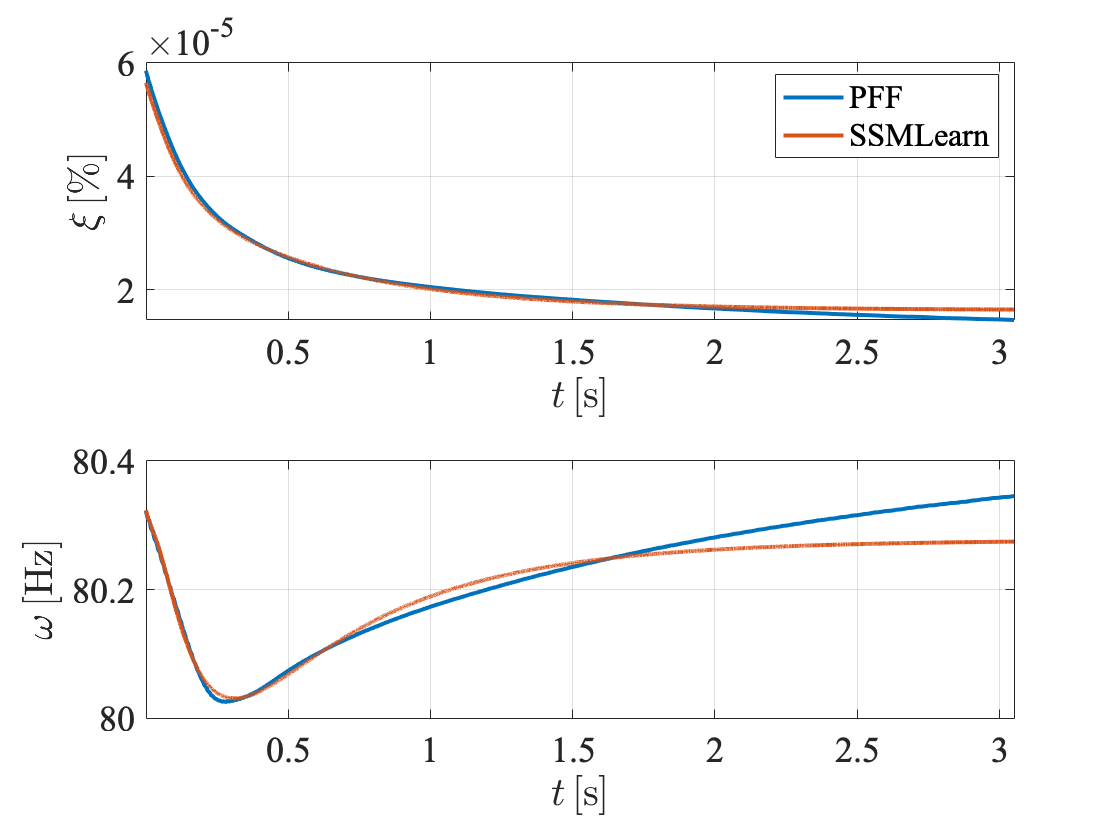

% Backbone Curves
figure;
subplot(211); hold on; grid on; box on;
plot(data_BRB.PFFResultsACC.Time(idx_acc,:)-data_BRB.PFFResultsACC.Time(idx_acc,1),data_BRB.PFFResultsACC.Damping(idx_acc,:)/100,'Linewidth',2,'DisplayName','PFF')
plot(tRec,damprDIC/100,'Linewidth',2,'DisplayName','SSMLearn')
xlabel('$t \, [$s$]$','interpreter','latex'); 
ylabel('$\xi \, [$\%$]$','interpreter','latex'); 
set(gca,'fontname', 'times'); set(gca,'fontsize', 18); 
legend
xlim([tRec(1) tRec(end)])
subplot(212); hold on; grid on; box on;
plot(data_BRB.PFFResultsACC.Time(idx_acc,:)-data_BRB.PFFResultsACC.Time(idx_acc,1),data_BRB.PFFResultsACC.Frequency(idx_acc,:),'Linewidth',2,'DisplayName','PFF')
plot(tRec,freqDIC,'Linewidth',2,'DisplayName','SSMLearn')
xlabel('$t \, [$s$]$','interpreter','latex'); 
ylabel('$\omega \, [$Hz$]$','interpreter','latex'); 
set(gca,'fontname', 'times'); set(gca,'fontsize', 18); 
xlim([tRec(1) tRec(end)])